disp('Question 1');

Question 1


disp('(7,4) Hamming Code');

(7,4) Hamming Code


n=7;
k=4;
u=n-k;

%{
 We define parity as:-
p1=m0+m1+m2
p2=m1+m2+m3
p3=m0+m1+m3

Therefore first 4 rows are 4x4 identity matrix and next 3 rows are the
parity checkers.
%}

% Parity matrix
P=[
   1 1 0 1;
   1 0 1 1;
   0 1 1 1;
   ]

P =      1     1     0     1
     1     0     1     1
     0     1     1     1



identity_matrix=eye(k);
G=[identity_matrix;P];
disp('Generator Matrix:');

Generator Matrix:


disp(G);

     1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1
     1     1     0     1
     1     0     1     1
     0     1     1     1



identity_parity=eye(u);
H=[P identity_parity];
disp('Parity Check Matrix:');

Parity Check Matrix:


disp(H);

     1     1     0     1     1     0     0
     1     0     1     1     0     1     0
     0     1     1     1     0     0     1



decnum=0:(2^k-1);
binnum=dec2bin(decnum);
M=zeros(k,length(decnum));

for i=1:length(decnum)
    M(:,i)=binnum(i,:)-'0';
end

disp('Matrix representing all possible length k(here 4) sequences:');

Matrix representing all possible length k(here 4) sequences:


disp(M);

     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1
     0     0     0     0     1     1     1     1     0     0     0     0     1     1     1     1
     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1     1
     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1



C=mod(G*M,2);
disp('All possible Codeword Matrix(length 7):');

All possible Codeword Matrix(length 7):


disp(C);

     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1
     0     0     0     0     1     1     1     1     0     0     0     0     1     1     1     1
     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1     1
     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1
     0     1     0     1     1     0     1     0     1     0     1     0     0     1     0     1
     0     1     1     0     0     1     1     0     1     0     0     1     1     0     0     1
     0     1     1     0     1     0     0     1     0     1     1     0     1     0     0     1



w=sum(C);
w_min=min(w(2:length(C)));
disp(['Minimum Hamming Weight=',num2str(w_min)]);

Minimum Hamming Weight=3



d_hmin=k;
for cdwrd1=1:length(C)
    for cdwrd2=cdwrd1+1:length(C)
        d_h=sum(xor(C(:,cdwrd1),C(:,cdwrd2)));
        d_hmin=min(d_h,d_hmin);
    end
end

disp(['Minimum Hamming Distance:',num2str(d_hmin)]);

Minimum Hamming Distance:3


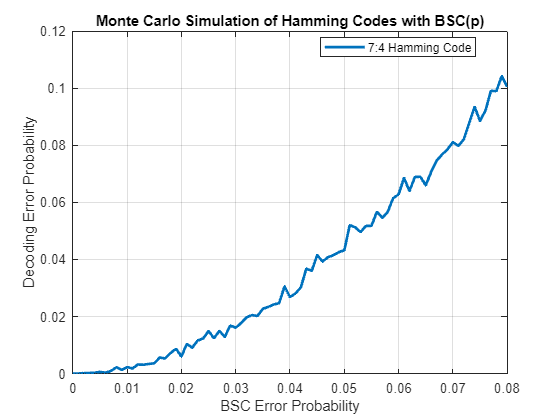

err=zeros(size(0:0.001:0.08));
nsim=1e4;

for p = 0:0.001:0.08 % Iterate over different error probabilities
for ksim = 1:nsim
m_in = randi([1, 2^k]); % Randomly select a message index
m = M(:, m_in); % Get the message corresponding to the index
c = C(:, m_in); % Get the codeword corresponding to the message
% Introduce BSC noise
bsc_noise = rand(size(c)) < p;
r = mod(c + bsc_noise, 2); % Received codeword
e=r-C;
answer = sum(abs(e));
[~,est_index] = min(answer);
% Check for error
if est_index ~= m_in
err(round(p * 1000) + 1) = err(round(p * 1000) + 1) + 1; % Increment error count
end
end
end
% Convert error counts to error probabilities
err_prob= err / nsim;
% Plotting
p_values = 0:0.001:0.08;
plot(p_values, err_prob,'LineWidth',2);
xlabel('BSC Error Probability');
legend('7:4 Hamming Code','location','best');
ylabel('Decoding Error Probability');
title('Monte Carlo Simulation of Hamming Codes with BSC(p)');
grid("on");

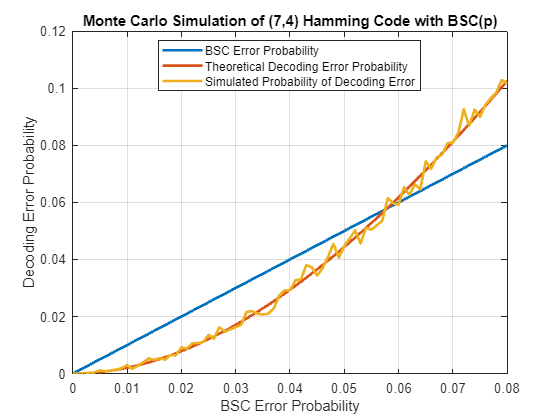

err = zeros(size(0:0.001:0.08)); % Simulated error count
theoretical_err = zeros(size(0:0.001:0.08)); % Theoretical error probability
nsim = 1e4; % Number of simulations
t_c=1;
for p = 0:0.001:0.08 % Iterate over different error probabilities
% Calculate theoretical probability of decoding error
% Hamming code minimum distance
d_min = 3;
% Theoretical probability of decoding error for Hamming code
for t = t_c+1:n
theoretical_err(round(p * 1000) + 1) = theoretical_err(round(p * 1000) + 1) + nchoosek(n, t) * p^t * (1-p)^(n-t);
end
for ksim = 1:nsim
m_in = randi([1, 16]); % Randomly select a message index
m = M(:, m_in); % Get the message corresponding to the index
c = C(:, m_in); % Get the codeword corresponding to the message
% Introduce BSC noise
bsc_noise = rand(size(c)) < p;
r = mod(c + bsc_noise, 2); % Received codeword
e=r-C;
answer = sum(abs(e));
[~,est_index] = min(answer);
% Check for error
if est_index ~= m_in
err(round(p * 1000) + 1) = err(round(p * 1000) + 1) + 1; % Increment error count
end
end
end
% Convert error counts to error probabilities
err_prob = err / nsim;
% Plotting
p_values = 0:0.001:0.08;
plot(p_values, p_values,'Color', '#0072BD', 'LineWidth', 2);
hold on;
plot(p_values, theoretical_err,'Color', '#D95319', 'LineWidth', 2);
plot(p_values, err_prob,'Color', '#EDB120', 'LineWidth', 2);
legend('BSC Error Probability', 'Theoretical Decoding Error Probability','Simulated Probability of Decoding Error',Location='best');
xlabel('BSC Error Probability');
ylabel('Decoding Error Probability');
title('Monte Carlo Simulation of (7,4) Hamming Code with BSC(p)');
grid on;
hold off;

disp('Question 2');

Question 2


disp('(14,8) RPC Code');

(14,8) RPC Code


n=14;
k=8;
u=n-k;

P=[
   1 0 0 0 1 0 0 0;
   0 1 0 0 0 1 0 0;
   0 0 1 0 0 0 1 0;
   0 0 0 1 0 0 0 1;
   1 1 1 1 0 0 0 0;
   0 0 0 0 1 1 1 1];

identity_matrix=eye(k);
G=[identity_matrix; P];
disp('Generator Matrix:');

Generator Matrix:


disp(G);

     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1
     1     0     0     0     1     0     0     0
     0     1     0     0     0     1     0     0
     0     0     1     0     0     0     1     0
     0     0     0     1     0     0     0     1
     1     1     1     1     0     0     0     0
     0     0     0     0     1     1     1     1




identity_parity=eye(u);
H=[P identity_parity];
disp('Parity Check Matrix:');

Parity Check Matrix:


disp(H);

     1     0     0     0     1     0     0     0     1     0     0     0     0     0
     0     1     0     0     0     1     0     0     0     1     0     0     0     0
     0     0     1     0     0     0     1     0     0     0     1     0     0     0
     0     0     0     1     0     0     0     1     0     0     0     1     0     0
     1     1     1     1     0     0     0     0     0     0     0     0     1     0
     0     0     0     0     1     1     1     1     0     0     0     0     0     1



decnum=0:(2^k-1);
binnum=dec2bin(decnum);
M=zeros(k,length(decnum));

for i=1:length(decnum)
    M(:,i)=binnum(i,:)-'0';
end

disp('Matrix representing all possible length k(here 8) sequences:');

Matrix representing all possible length k(here 8) sequences:


disp(M);

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1    

C=mod(G*M,2);
disp('All possible Codeword Matrix(length 14):');

All possible Codeword Matrix(length 14):


disp(C);

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1    

w=sum(C);
w_min=min(w(2:length(C)));
disp(['Minimum Hamming Weight=',num2str(w_min)]);

Minimum Hamming Weight=3



d_hmin=k;
for cdwrd1=1:length(C)
    for cdwrd2=cdwrd1+1:length(C)
        d_h=sum(xor(C(:,cdwrd1),C(:,cdwrd2)));
        d_hmin=min(d_h,d_hmin);
    end
end

disp(['Minimum Hamming Distance:',num2str(d_hmin)]);

Minimum Hamming Distance:3


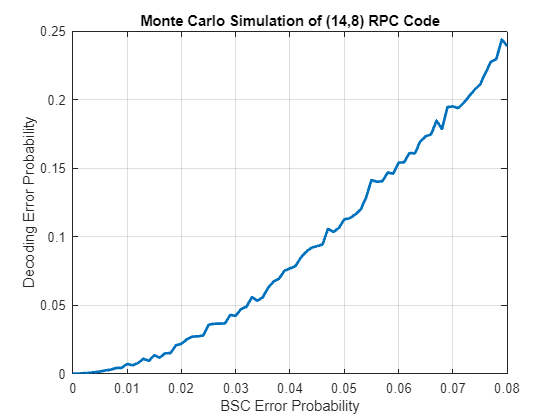

err=zeros(size(0:0.001:0.08));
nsim=1e4;

for p = 0:0.001:0.08 % Iterate over different error probabilities
for ksim = 1:nsim
m_in = randi([1, 2^k]); % Randomly select a message index
m = M(:, m_in); % Get the message corresponding to the index
c = C(:, m_in); % Get the codeword corresponding to the message
% Introduce BSC noise
bsc_noise = rand(size(c)) < p;
r = mod(c + bsc_noise, 2); % Received codeword
e=r-C;
answer = sum(abs(e));
[~,est_index] = min(answer);
% Check for error
if est_index ~= m_in
err(round(p * 1000) + 1) = err(round(p * 1000) + 1) + 1; % Increment error count
end
end
end
% Convert error counts to error probabilities
err_prob_1= err / nsim;
% Plotting
p_values = 0:0.001:0.08;
plot(p_values, err_prob_1,'LineWidth',2);
xlabel('BSC Error Probability');
ylabel('Decoding Error Probability');
title('Monte Carlo Simulation of (14,8) RPC Code');
grid("on");

% Comparing RPC and Hamming Code
disp('Comparing Hamming Code with RPC Code.');

Comparing Hamming Code with RPC Code.


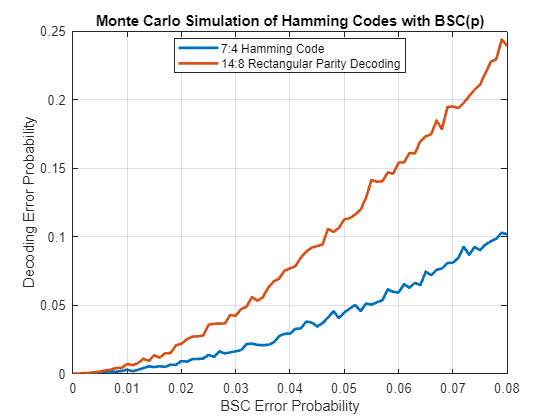

figure;
p_values = 0:0.001:0.08;
plot(p_values, err_prob,'LineWidth',2);
hold on;
plot(p_values, err_prob_1,'LineWidth',2);
xlabel('BSC Error Probability');
legend('7:4 Hamming Code','14:8 Rectangular Parity Decoding','location','best');
ylabel('Decoding Error Probability');
title('Monte Carlo Simulation of Hamming Codes with BSC(p)');
grid("on");
hold off;


% From the above graph it is clear that the Hamming Code performs better
% though the rate are same for both.
% The reason behind this lies in the theory of perfect codes.
%{
r=4/7 and r=8/14(4/7) both have same rate but to check whether one is a
perfect code or not we show:
2^k.Volume(n,tc)=2^n or not where tc= # of correction bits and
Volume(n,tc)=sum(n choose i) { i=0 to tc)

For r=4/7
there are 16 hamming spheres and 16*8 binary sequences.
where 2^n=16*18=128
Hence a perfect Code

For r=4/7 but with k=8 and n=14
2^8 * 15 cannot be 2^14 
Hence not a perfect code

Hence Hamming Code is better than RPC Code
%}


disp('Question 3');

Question 3


disp('(9,4) Product Code');

(9,4) Product Code


n=9;
k=4;
u=n-k;

P=[
  1 0 1 0;
  0 1 0 1;
  1 1 0 0;
  0 0 1 1;
  1 1 1 1];

identity_matrix=eye(k);
identity_parity=eye(u);
G=[identity_matrix; P];
H=[P identity_parity];
disp('Generator Matrix:');

Generator Matrix:


disp(G);

     1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1
     1     0     1     0
     0     1     0     1
     1     1     0     0
     0     0     1     1
     1     1     1     1



disp('Parity Check Matrix:');

Parity Check Matrix:


disp(H);

     1     0     1     0     1     0     0     0     0
     0     1     0     1     0     1     0     0     0
     1     1     0     0     0     0     1     0     0
     0     0     1     1     0     0     0     1     0
     1     1     1     1     0     0     0     0     1



decnum=0:(2^k-1);
binnum=dec2bin(decnum);
M=zeros(k,length(decnum));

for i=1:length(decnum)
    M(:,i)=binnum(i,:)-'0';
end

disp('Matrix representing all possible length k(here 4) sequences:');

Matrix representing all possible length k(here 4) sequences:


disp(M);

     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1
     0     0     0     0     1     1     1     1     0     0     0     0     1     1     1     1
     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1     1
     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1



C=mod(G*M,2);
disp('All possible Codeword Matrix(length 9):');

All possible Codeword Matrix(length 7):


disp(C);

     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1
     0     0     0     0     1     1     1     1     0     0     0     0     1     1     1     1
     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1     1
     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1
     0     0     1     1     0     0     1     1     1     1     0     0     1     1     0     0
     0     1     0     1     1     0     1     0     0     1     0     1     1     0     1     0
     0     0     0     0     1     1     1     1     1     1     1     1     0     0     0     0
     0     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0
     0     1     1     0     1     0     0     1     1     0     0     1     0     1     1     0



w=sum(C);
w_min=min(w(2:length(C)));
disp(['Minimum Hamming Weight=',num2str(w_min)]);

Minimum Hamming Weight=4



d_hmin=k;
for cdwrd1=1:length(C)
    for cdwrd2=cdwrd1+1:length(C)
        d_h=sum(xor(C(:,cdwrd1),C(:,cdwrd2)));
        d_hmin=min(d_h,d_hmin);
    end
end

disp(['Minimum Hamming Distance:',num2str(d_hmin)]);

Minimum Hamming Distance:4


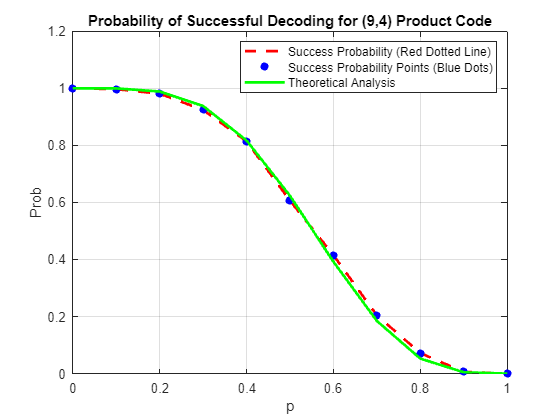

err = zeros(size(0:0.1:1));% Initialize array to store error counts for each p
theoretical_prob = zeros(size(0:0.1:1));
nsim = 1000; % Number of simulations
for p = 0:0.1:1 % Iterate over different erasure probabilities
    for ksim = 1:nsim
        m_in = randi([1, 2^k]); % Randomly select a message index
        m = M(:, m_in); % Get the message corresponding to the index
        c = C(:, m_in); % Get the codeword corresponding to the message
        bec_noise = rand(size(c)) < p;
        % Apply BEC noise
        num = 5 * bec_noise; % Treat terms with more than 1 erasure as erasures
        r = num + c; % Received codeword
        % Set values greater than 4 to NaN
        r(r > 4) = NaN;
        theoretical_prob = binopdf(0, n, p_values) + binopdf(1, n, p_values) + binopdf(2, n, p_values) + binopdf(3, n, p_values) + binopdf(4, n, p_values) + binopdf(5, n, p_values) / 2;
        % Reshape the received codeword into a 3x3 matrix
        r_reshaped = [r(1), r(2), r(5); r(3), r(4), r(6); r(7), r(8), r(9)];

        % Perform iterative decoding
        for iter = 1:3 % Iterations for both row and column decoding
            % Column decoding
            for col = 1:3
                nan_indices = find(isnan(r_reshaped(:, col)));
                if length(nan_indices) == 1 % Exactly one NaN in the column
                % Find non-NaN indices
                    non_nan_indices = find(~isnan(r_reshaped(:, col)));
                    % XOR the other two elements
                    r_reshaped(nan_indices, col) = mod(sum(r_reshaped(non_nan_indices, col)), 2);
                end
            end
            % Row decoding
            for row = 1:3
                nan_indices = find(isnan(r_reshaped(row, :)));
                if length(nan_indices) == 1 % Exactly one NaN in the row
                    % Find non-NaN indices
                    non_nan_indices = find(~isnan(r_reshaped(row, :)));
                    % XOR the other two elements
                    r_reshaped(row, nan_indices) = mod(sum(r_reshaped(row,non_nan_indices)), 2);
               end
           end
        end
        % Check for remaining NaNs
        if any(isnan(r_reshaped), 'all')
            err(round(p * 10) + 1) = err(round(p * 10) + 1) + 1; % Increment error count
        end
    end
end
% Convert error counts to error probabilities
err_prob = err / (nsim);
succ_prob = zeros(size(0:0.1:1)); % Initialize array to store error counts for each p
succ_prob = 1-err_prob;
% Plotting
p_values = 0:0.1:1;
plot(p_values, succ_prob, 'r--', 'LineWidth', 2);
hold on; % Hold the plot to add more elements
% Plotting the blue dots
scatter(p_values, succ_prob, 'b', 'filled');
plot(p_values, theoretical_prob, 'g', 'LineWidth', 2);
hold off; % Release the hold
xlabel('p');
ylabel('Prob');
title('Probability of Successful Decoding for (9,4) Product Code');
ylim([0 1.2]);
grid on;
% Adding legend
legend('Success Probability (Red Dotted Line)', 'Success Probability Points (Blue Dots)','Theoretical Analysis');